clear
time1 = [0:0.1:5];
velocity1 = time1.^2;
acceleration1 = gradient(velocity1, time1);
plot(time1, velocity1);
grid on
hold on
plot(time1, acceleration1);


time2 = [5:0.1:10];
velocity2 = 2*time2+15;
acceleration2 = gradient(velocity2, time2);
plot(time2, velocity2);
plot(time2, acceleration2);
xlabel('Time (s)');
ylabel('Velocity and Acceleration');
title('Velocity and Acceleration vs Time');


time3 = [10:0.1:15];
velocity3 = 35*ones(size(time3));
acceleration3 = gradient(velocity3, time3);
plot(time3, velocity3);
plot(time3, acceleration3);

time4 = [15:0.1:20];
velocity4 = -(time4-15).^2 + 35

velocity4 =    35.0000   34.9900   34.9600   34.9100   34.8400   34.7500   34.6400   34.5100   34.3600   34.1900   34.0000   33.7900   33.5600   33.3100   33.0400   32.7500   32.4400   32.1100   31.7600   31.3900   31.0000   30.5900   30.1600   29.7100   29.2400   28.7500   28.2400   27.7100   27.1600   26.5900   26.0000   25.3900   24.7600   24.1100   23.4400   22.7500   22.0400   21.3100   20.5600   19.7900   19.0000   18.1900   17.3600   16.5100   15.6400   14.7500   13.8400   12.9100   11.9600   10.9900


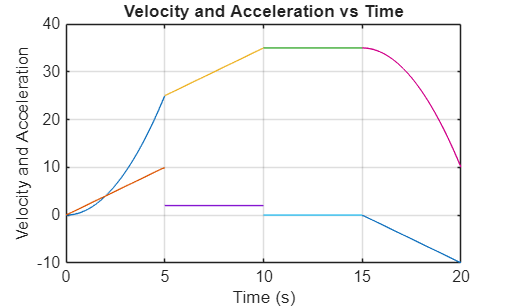

acceleration4 = gradient(velocity4, time4);
plot(time4, velocity4);
plot(time4, acceleration4);
hold off


% Compute integrals of each acceleration curve over their position intervals
I1 = trapz(time1, acceleration1);
I2 = trapz(time2, acceleration2);
I3 = trapz(time3, acceleration3);
I4 = trapz(time4, acceleration4);

% Display results
fprintf('Fuel Usage for acceleration over time:\n');

Fuel Usage for acceleration over time:


fprintf('Segment 1 (%.1f to %.1f): %g gallons\n', time1(1), time1(end), I1/10);

Segment 1 (0.0 to 5.0): 2.5 gallons


fprintf('Segment 2 (%.1f to %.1f): %g gallons\n', time2(1), time2(end), I2/10);

Segment 2 (5.0 to 10.0): 1 gallons


fprintf('Segment 3 (%.1f to %.1f): %g gallons\n', time3(1), time3(end), I3);

Segment 3 (10.0 to 15.0): 0 gallons


fprintf('Segment 4 (%.1f to %.1f): %g gallons\n', time4(1), time4(end), 0);

Segment 4 (15.0 to 20.0): 0 gallons


## Analysis

% Shown on the graph is the velocity and the acceleration of a vehicle as
% it moves over time. We can see that the car initially starts at rest,
% then accelerates at an increasing rate until the velocity reaches 25m/s.
% Then, the car accelerates at a constant rate until the velocity reaches
% 35m/s. The car then cruises for five seconds, and then hits the brakes.

% Below, we can see the acceleration of the car. It starts off by
% increasing, and then stays constant, then is at 0, then decreases as the
% car slows down. If we take the integral of the acceleration, we can get a
% rough idea for how much fuel the car is consuming as it drives. For
% example, in order to get the car up to speed, it needs to consume 2.5
% gallons, but once it starts steadily increasing, it only needs to consume
% 1 gallon. The car consumes no gas when it is both cruising AND when it is
% slowing down. If you notice, it does not matter how fast the car is
% moving, the fuel consumption depends on the usage of the engine, which is
% represented by what magnitude the car is accelerating. Its peak fuel
% usage is right before 5 seconds, when the car is accelerating the most. 